clear all
clc

x = linspace(-0.007,0.007,501);
[X,Y] = meshgrid(x,x);
[phi,r] = cart2pol(X,Y);

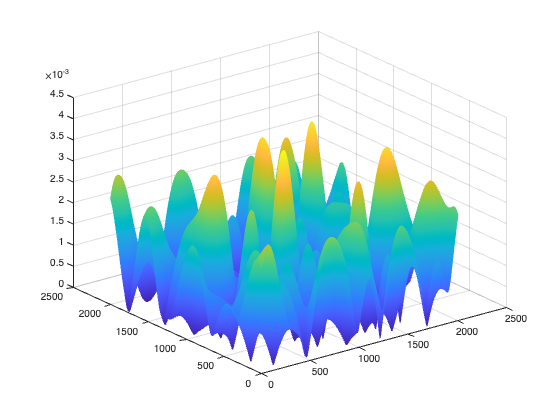

U = rand(501,501);
U1 = fft2(U);
fil = r < 0.00004;   % 0.005 mm
U2 = fil .* U1 ;

U3 = ifft2(U2);

U4 = abs(U3);
mesh(U4)

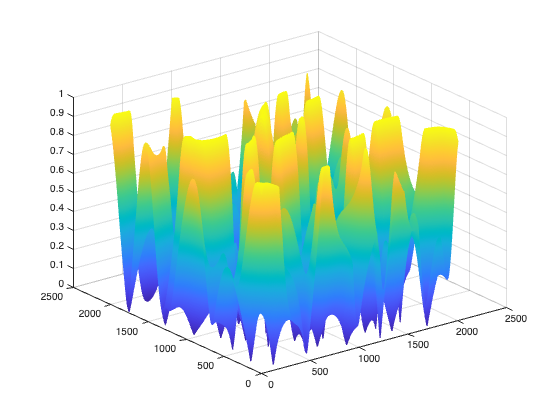

U5 = U4 ./ max(U4);
mesh(U5)

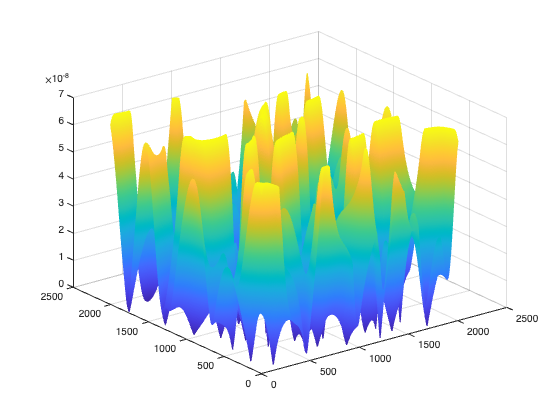

U6 = 70 .* 10^(-9) .* U5;
mesh(U6)

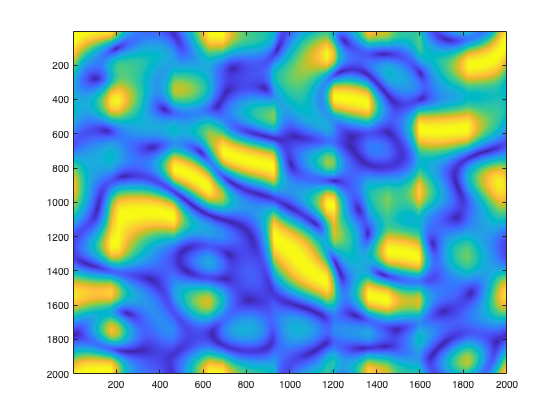

imagesc(U6)

randomSurf = U6;

% Parameters
lambda = 633e-9; 
k = 2.*pi./lambda;           
w01 = 2e-3;
w02 = w01;
z = 0;              
p1 = input("enter radial index = ");   
l1 = input("enter azimuthal index = "); 
p2 = p1;   
l2 = -l1;
zR1 = pi * w01.^2 ./ lambda;   % Rayleigh range
w1 = w01 * sqrt(1 + z.^2 / zR1.^2);
R_inverse = z./(zR1.^2 + z.^2);

% amplitude part
mod_l = abs(l1);

Unrecognized function or variable 'l1'.

A0 = ((sqrt(2).*r./w1).^mod_l)./w1;

% phase part
T1 = (pi.*(r.^2).*R_inverse./lambda);
T2 = (mod_l + 2*p1 + 1).*atan(z./zR1);
T3 = 1i.*(T1-T2);
Phase = exp(T3);

% Spiral Phase
P = exp(1i.*l1.*phi);
gauss = exp(-(r.^2)./(w1.^2));
lgu = laguerreL(p1,l1,2.*gauss);
R_function = A0 .* lgu .* gauss .* Phase;
rs = load("randSurf", "U6");
rs = rs.U6;
delta = rs

% Plot
G1_ideal = R_function .* exp(1i.*l2.*phi);
G2_ideal = R_function .* exp(1i.*l1.*phi);
G_ideal = G1_ideal + G2_ideal;
a1_ideal = max((abs(G_ideal)).^2);
a2_ideal = max(a1_ideal);
Iid = ((abs(G_ideal)).^2)./a2_ideal;
% Iid = abs(G1+G2).^2;
figure; imagesc(Iid);
phaseid = angle(G1_ideal+G2_ideal);
%figure; imagesc(phaseid);

% Plot
G1 = R_function .* exp(1i.*(l2.*phi + 2.*k.*delta));
G2 = R_function .* exp(1i.*l1.*phi);
G = G1 + G2;
a1 = max((abs(G)).^2);
a2 = max(a1);
Idis = ((abs(G)).^2)./a2;
% Idis = abs(G1+G2).^2;
figure; imagesc(Idis);
phasedis = angle(G1+G2);
%figure; imagesc(phasedis);